Create Transmission Environment for Simulation of Path Planning Algorithms

% Clear everything
clear;clc;
% Create Truck Transmission Model SM-465
% Visualising the Transmission Model in Initial Position 
% Initialising a figure to display our Model 
figure;
% Creating the MainShaft and CountersShaft along with walls
main_shaft = Mainshaft();
show(main_shaft, 'Collisions',"on",'Visuals',"off");
% Set the figure t
% o hold
hold on;
% Draw walls in the environment of the robotic system.
display_walls();
% Draw the fixed Shaft in the Environment
display_Countershaft();
%Axis limit Plots
xlim([0 10])
ylim([-5 5])
zlim([-6 6])
hold off;

Lets Plan the Path for Transmission Gear using RRT!

% Initialising a figure to display our Model 
figure;
% Creating the MainShaft and CountersShaft along with walls
main_shaft = Mainshaft();
show(main_shaft, 'Collisions',"on",'Visuals',"off");
% Set the figure to hold
hold on;
% Draw walls in the environment of the robotic system.
display_walls();
% Draw the fixed Shaft in the Environment
display_Countershaft();
% Axis limit Plots
xlim([0 10])
ylim([-5 5])
zlim([-6 6])

% Planning path 
path = path_planning();

collision_count = 251

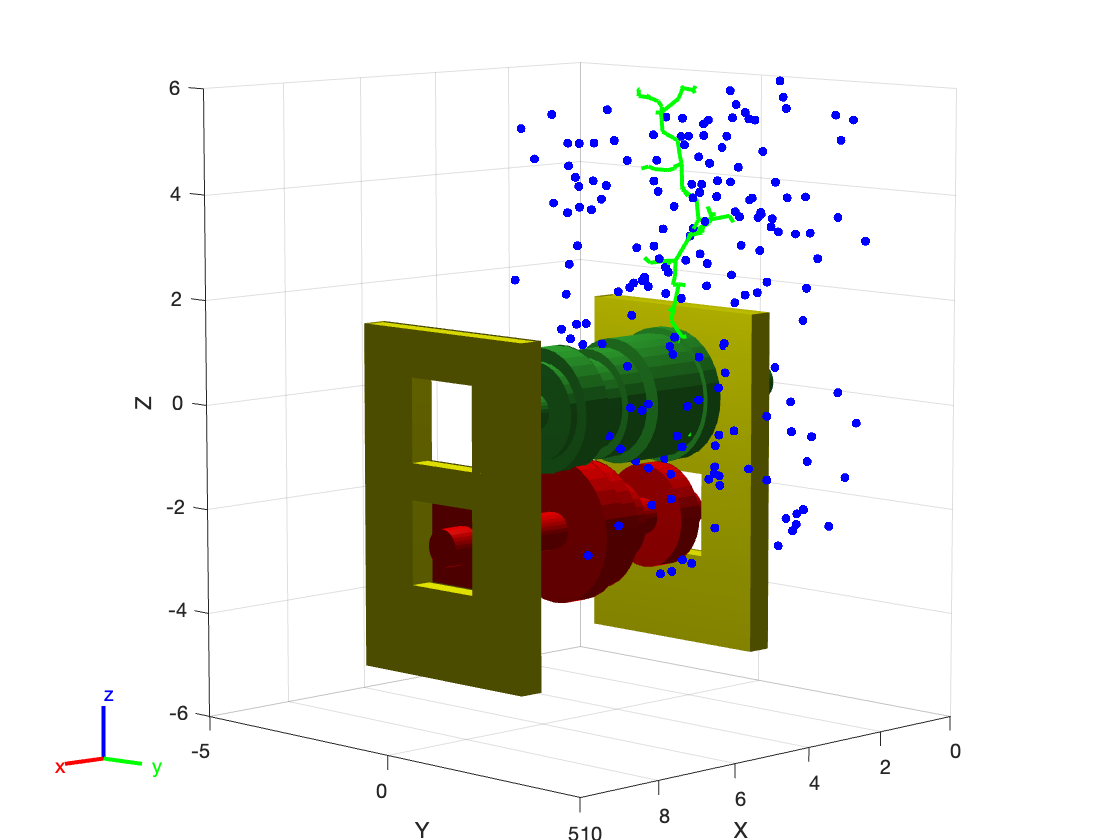

hold off;

Animate and display the path found from Motion Planner RRT

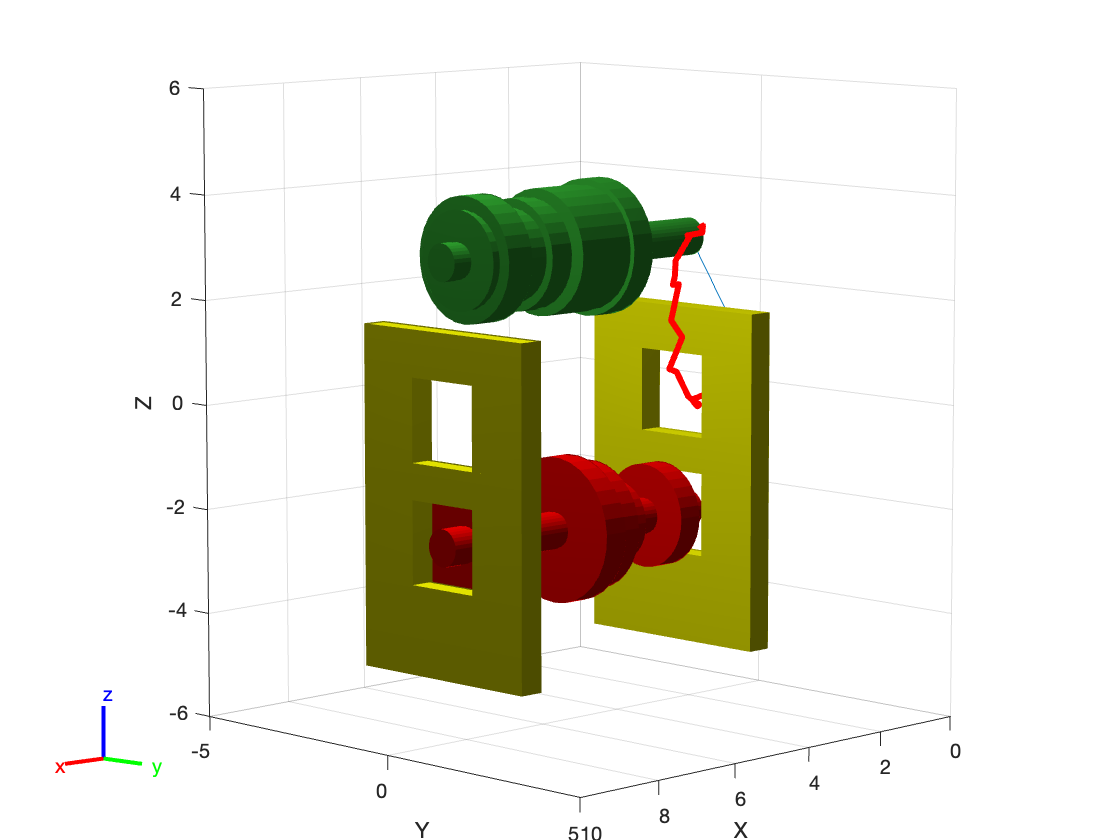

% Initialising a figure to display our Model 
figure;
% Creating the MainShaft and CountersShaft along with walls
pose_goal = [2 0 3 0 0 0];
goal_shaft = pose(pose_goal);
show(goal_shaft, 'Collisions',"on",'Visuals',"off");
% Axis limit Plots
xlim([0 10])
ylim([-5 5])
zlim([-6 6])
hold on;
% Draw walls in the environment of the robotic system.
display_walls();
% Draw the fixed Shaft in the Environment
display_Countershaft();
% Draw path generated
draw_path(path);
hold off;

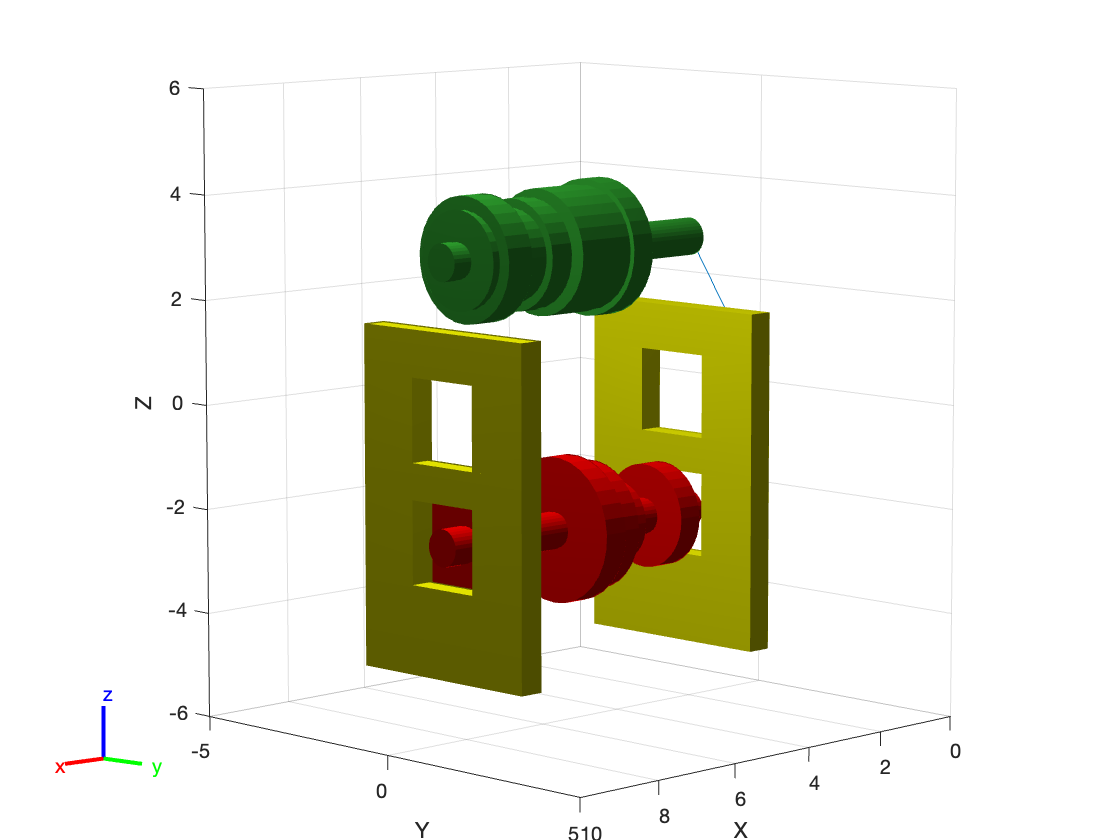

% Animate the path generated from start to goal pose 
animate_path(path);

Functions for Creating and Displaying Environment 

function counter_shaft = display_Countershaft()
    % This function creates a counter shaft by generating a set of cylinders 
    % Define the scale and positions of the cylinders
    scale = 2;
    translations = [0.38, 0, -2.31; 1.01, 0, -2.31; 1.64, 0, -2.31; 2.27, 0, -2.31; 2.6, 0, -2.31; 2.91, 0, -2.31; 3.43, 0, -2.31; 4.59, 0, -2.31; 5.75, 0, -2.31; 6.3, 0, -2.31];
    % Define the lengths and radii of the cylinders
    lengths = [0.76, 0.5, 0.76, 0.5, 0.16, 0.5, 0.5, 1.82, 0.5, 0.6];
    % Radius of Each Cylinder
    radii = [0.36, 1, 0.36, 0.8, 0.36, 1.235, 1.395, 0.36, 1.40, 0.36];
    
    % Create an empty cell array to store the cylinders
    counter_shaft = {};
    % Create each cylinder and display it
    for i = 1:length(translations)
        % Calculate the position, length, and radius of the current cylinder
        translation = translations(i, :) + [scale, 0, 0];
        % Create the current cylinder
        cylinder = collisionCylinder(radii(i), lengths(i));
        tform = trvec2tform(translation);
        cylinder.Pose = tform * axang2tform([0 1 0 pi/2]);
        % Add the current cylinder to the cell array
        counter_shaft{end+1} = cylinder;
        % Display the current cylinder with the given color
        [~, obj] = show(cylinder);
        % Set the color for the cylinders
        obj.FaceColor = [1 0 0];
        obj.EdgeColor = 'none';
    end
end


function walls = display_walls()
    % Define the scaling factor 
    scale = 2;
    % Define the dimensions and positions of the right and left walls of
    right_wall = [0.5, 4.2, 1.7, 0.25,0, -3.95; 0.5, 1.3, 1.6, 0.25, 1.45, -2.3;0.5, 1.3, 1.6, 0.25, -1.45, -2.3;0.5, 4.2, 0.7, 0.25, 0, -1.15;0.5, 1.3, 1.6, 0.25, 1.45, 0; 0.5, 1.3, 1.6, 0.25, -1.45, 0;0.5, 4.2, 0.9, 0.25, 0, 1.25];
    left_wall = [0.5, 4.2, 1.7, 6.35, 0, -3.95;0.5, 1.3, 1.6, 6.35, 1.45, -2.3;0.5, 1.3, 1.6, 6.35, -1.45, -2.3; 0.5, 4.2, 0.7, 6.35, 0, -1.15;0.5, 1.3, 1.6, 6.35, 1.45, 0;0.5, 1.3, 1.6, 6.35, -1.45, 0;0.5, 4.2, 0.9, 6.35, 0, 1.25];
    % Concatenate the right and left walls into a single matrix
    boxes = [left_wall; right_wall];
    % Create an empty cell array to store the collision boxes
    walls = {};
    
    % Create collision boxes for each wall and add them to the walls array
    for i = 1:size(boxes, 1)
        wall = boxes(i,:);
        % Create a collision box with the specified dimensions
        box = collisionBox(wall(1), wall(2), wall(3));
        % Define the transformation matrix to position the box in the scene
        transformation = [eye(3) (wall(4:6) + [scale, 0, 0])'; 0 0 0 1];
        box.Pose = transformation;
        % Add the box to the walls cell array
        walls{end+1} = box;
        % Show the box in the scene and set its color and edge properties
        [~, obj] = show(box);
        obj.FaceColor = [1 1 0];
        obj.EdgeColor = 'none';
    end
end

function shaft = Mainshaft()
    % Define the lengths and radii of the cylinders 
    % Model the main shaft
    lengths = [6.6,0.5,1.25,0.16,0.5,0.65,0.6,0.16];
    radii = [0.36,1.3,1.2,0.9,1.06,0.9,1.195,0.95];

    % Define Denavit-Hartenberg (DH) parameters for the main shaft and its cylinders
    dh_params=[0 0 0 pi/2;
                 2.36 0 0 0;
                 .5 0 0 0;
                 1.25 0 0 0;
                 .16 0 0 0;
                 .5 0 0 0;
                 .65 0 0 0;
                 .6 0 0 0;
                 .16 0 0 0];
    % Create rigid body tree object
    shaft = rigidBodyTree("DataFormat", "column");
    % Define base name for the tree
    basename=shaft.BaseName;
    % Create rigid body objects for each cylinder and set their joints and transforms
    cylinder_1 = rigidBody('cylinder_1');
    cylinder_2 = rigidBody('cylinder_2');
    cylinder_3 = rigidBody('cylinder_3');
    cylinder_4 = rigidBody('cylinder_4');
    cylinder_5 = rigidBody('cylinder_5');
    cylinder_6 = rigidBody('cylinder_6');
    cylinder_7 = rigidBody('cylinder_7');
    cylinder_8 = rigidBody('cylinder_8');
    
    % Define joint 1 as revolute and set its axis and transform
    joint_1 = rigidBodyJoint('joint_1','revolute');
    joint_1.JointAxis=[0,1,0];
    cylinder_1.Joint=joint_1;
    setFixedTransform(joint_1,dh_params(1,:),'dh');
    % Define joints 2-8 as fixed and set their transforms
    joint_2 = rigidBodyJoint('joint_2','fixed');
    setFixedTransform(joint_2,dh_params(2,:),'dh');
    cylinder_2.Joint=joint_2;
    
    joint_3 = rigidBodyJoint('joint_3','fixed');
    setFixedTransform(joint_3,dh_params(3,:),'dh');
    cylinder_3.Joint=joint_3;
    
    joint_4 = rigidBodyJoint('joint_4','fixed');
    setFixedTransform(joint_4,dh_params(4,:),'dh');
    cylinder_4.Joint=joint_4;
    
    joint_5 = rigidBodyJoint('joint_5','fixed');
    setFixedTransform(joint_5,dh_params(5,:),'dh');
    cylinder_5.Joint=joint_5;
    
    joint_6 = rigidBodyJoint('joint_6','fixed');
    setFixedTransform(joint_6,dh_params(6,:),'dh');
    cylinder_6.Joint=joint_6;
    
    joint_7 = rigidBodyJoint('joint_7','fixed');
    setFixedTransform(joint_7,dh_params(7,:),'dh');
    cylinder_7.Joint=joint_7;
    
    joint_8 = rigidBodyJoint('joint_8','fixed');
    setFixedTransform(joint_8,dh_params(8,:),'dh');
    cylinder_8.Joint=joint_8;
    
    %Adds bodies to shaft 
    addBody(shaft, cylinder_1, basename);
    addBody(shaft, cylinder_2, 'cylinder_1');
    addBody(shaft, cylinder_3, 'cylinder_2');
    addBody(shaft, cylinder_4, 'cylinder_3');
    addBody(shaft, cylinder_5, 'cylinder_4');
    addBody(shaft, cylinder_6, 'cylinder_5');
    addBody(shaft, cylinder_7, 'cylinder_6');
    addBody(shaft, cylinder_8, 'cylinder_7');
    
    
    for i=1:length(radii)
        %Create Collision Cylinders
        collision_cylinder = collisionCylinder(radii(i),lengths(i));
        % Define the orientation of the collision cylinder
        axis = [0 1 0 pi/2];
        transformation = trvec2tform([lengths(i)/2,0,0])*axang2tform(axis);
        collision_cylinder.Pose = transformation;
        % Add the collision cylinder to the corresponding body in the shaft
        addCollision(shaft.Bodies{i}, collision_cylinder);
    end
end

Functions for Path Planing - RRT 

function path = find_path(node_goal)
    path = [];
    current_node = node_goal;
    while isstruct(current_node.parent)
        path = [path current_node];
        current_node = current_node.parent;
    end
    path = [path current_node];
    path = fliplr(path);
    if ~isstruct(node_goal.parent)
        path = [];
    end
end
     

function path = path_planning()
    % Define the start and goal nodes
    % Creates a new node object with the given pose and sets the parent field to -1
    node_start = struct("pose", [0 0 0 0 0 0], "parent", -1);
    node_goal = struct("pose", [2 0 3 0 0 0], "parent", -1);
    % Display the walls and countershaft
    walls = display_walls();
    counter_shaft = display_Countershaft;
    % Initialize the collision counter
    collision_count = 0;
     % Initialize the visited nodes list with the start node
    visited = [node_start];
     % Set the number of iterations for the algorithm
    iteration_counter = 2500;
    % Run the RRT algorithm for the set number of iterations
    for current_count=1:iteration_counter
        % Generate a random pose or the goal pose every 10 iterations
        if mod(current_count,10)==0
            random_pose=[2 0 3 0 0 0];
        else
            random_pose = get_random_pose();
        end
        random_node = struct("pose", random_pose, "parent", -1);

        
        % Extend the tree towards the randomly generated node 
        new_node = step(get_closest_node(random_node, visited), random_node, 0.1);
        
        % Plot the randomly generated node as a black 'x'
        plot3(random_pose(1), random_pose(2), random_pose(3), ...
            '.', 'Color', 'Blue','MarkerSize', 12);


        % Check for collisions
        if check_collisions(pose(new_node.pose), counter_shaft, walls) == 1
            % If a collision occurs, increment the collision counter and
            collision_count = collision_count+ 1;
             % continue to the next iteration
            continue
        end
        
        %Plot a line from the closest visited node to the newly generated
        close_node = get_closest_node(random_node, visited).pose(1,1:3);
        node_new = new_node.pose(1,1:3);
        line(...
            [close_node(1), node_new(1)], ...
            [close_node(2), node_new(2)], ...
            [close_node(3), node_new(3)], ...
            'Color', 'green', 'LineWidth', 2);
        drawnow;

        % Add the newly generated node to the visited nodes list
        visited(end+1) = new_node;
        
        dist_b = sqrt( ...
            (new_node.pose(1)-node_goal.pose(1))^2 + ...
            (new_node.pose(2)-node_goal.pose(2))^2 + ...
            (new_node.pose(3)-node_goal.pose(3))^2 ...
            );
        % Check if the newly generated node is close to the goal node
        if dist_b < 0.1
            node_goal.parent = new_node;
            break;
        end

    end
    % Display the number of collisions that occurred during the algorithm
    display(collision_count)
    % Generate the path from the start node to the goal node 
    path = find_path(node_goal);
end

  

function shaft = pose(pose)
    
    shaft = Mainshaft();
    % create a new rigid body tree
    new_tree = rigidBodyTree("DataFormat", "column");
    % create a new rigid body
    rigid_body = rigidBody("new_base");
    % create a transformation matrix based on the pose
    transform = trvec2tform([pose(1), pose(2), pose(3)]) * ...
        axang2tform([1 0 0 pose(4)]) * axang2tform([0 1 0 pose(5)]) * ...
        axang2tform([0 0 1 pose(6)]);
    % set the joint of the new rigid body to a fixed transform
    rigid_body.Joint.setFixedTransform(transform);
    % add the new rigid body to the new rigid body tree
    new_tree.addBody(rigid_body, 'base');
    % remove the "cylinder_1" body from the Mainshaft object and add it as
    % a subtree of the new rigid body tree
    tmp_tree = removeBody(shaft, "cylinder_1");
    new_tree.addSubtree('new_base', tmp_tree);
    % return the new rigid body tree as the updated Mainshaft object
    shaft = new_tree;
end


function new_node = step(start, towards, incremental_step)
   %Create a new node moved towards the target node's pose
    distance = sqrt( ...
        (start.pose(1)-towards.pose(1))^2+...
        (start.pose(2)-towards.pose(2))^2+...
        (start.pose(3)-towards.pose(3))^2 ...
        );
    new_node = struct("pose", start.pose + (towards.pose - start.pose) * incremental_step, "parent", start);
    if distance <= 0.1
        new_node = towards;
        new_node.parent = start;
    end
end


function random_pose = get_random_pose()
    % Define the bounds for the random pose
    bounds = [-1, 6, -1, 3, -3, 10, 0, 0, -pi/2, 2*pi/4, 0, 0];  

    % Initialize an array to store the random pose values
    random_pose = zeros(1,6);
    for i = 1:6
        random_pose(i) = rand()*(bounds(2*i)-bounds(2*i-1)) + bounds(2*i-1);
    end
end


function closest_node = get_closest_node(node, node_list)
    % Set minimum distance to infinity and closest node to empty
    min_distance = inf;
    closest_node = [];
    % Loop through each node in the list
    for i = 1:length(node_list)
        % Get the current node to be considered
        node_curr = node_list(i);
        %distance to the node
        distance = sqrt( ...
            (node.pose(1)-node_curr.pose(1))^2 + ...
            (node.pose(2)-node_curr.pose(2))^2 + ...
            (node.pose(3)-node_curr.pose(3))^2 ...
            );
        %if dist less than min_dist then update node
        if distance < min_distance
            min_distance = distance;
            closest_node = node_curr;
        end
    end
end


function collides = check_collisions(shaft, fixed_shaft, walls)
    % Get the home configuration of the rigid body tree
    home_config = homeConfiguration(shaft);
    % Combine collision objects into a single array
    collision_objects = [walls, fixed_shaft];
    for i = 1:numel(collision_objects)
        % Check for collisions between each collision object and the robot
        collisions = checkCollision(shaft, home_config, collision_objects(i));
        if collisions(2)
            % If a collision is detected, return immediately
            collides = 1;
            return
        end
    end
    % If no collisions are detected, return 0
    collides = 0;
end


function draw_path(path)
    xyz = reshape([path.pose], 6, [])';  % Extract x,y,z coordinates from each node
    start_xyz = xyz(1:end-1, 1:3);  % Extract starting coordinates for each line
    next_xyz = xyz(2:end, 1:3);  % Extract ending coordinates for each line
    plot3(start_xyz(:,1), start_xyz(:,2), start_xyz(:,3), 'r-', 'LineWidth', 3);  % Plot the path
    plot3(next_xyz(:,1), next_xyz(:,2), next_xyz(:,3), 'r-', 'LineWidth', 3);
    pause(10);
end

function animate_path(path)
    for i=1:length(path)
        % Clear the current figure
        clf;
        % Generate a shaft object from the current pose in the path
        shaft = pose(path(i).pose);
        % Show the shaft object with collision detection on and visuals off
        show(shaft,'Collisions',"on",'Visuals',"off");
        % Hold on to the current figure to add more objects to it
        hold on;
        % Display the walls and countershaft objects
        display_walls();
        display_Countershaft();
        % Set the limits for the x, y, and z axes
        xlim([0 10])
        ylim([-5 5])
        zlim([-6 6])
       % Update the figure window
       drawnow;
    end
end